# Resample Audio 

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code imports and preprocesses the audio file.

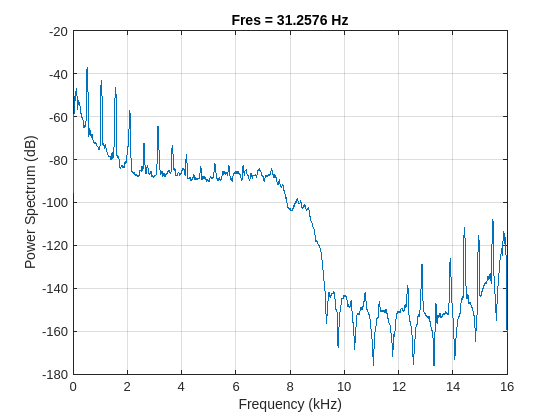

[flute, fs] = audioread("./data/NoisyFlute.wav");
flute = flute(1:7*fs);
fluteup = resample(flute, 2, 1);
fsup = fs*2;
pspectrum(fluteup,fsup)

## Task 1

Instead of generating the watermark, could you use another audio file as the watermark?

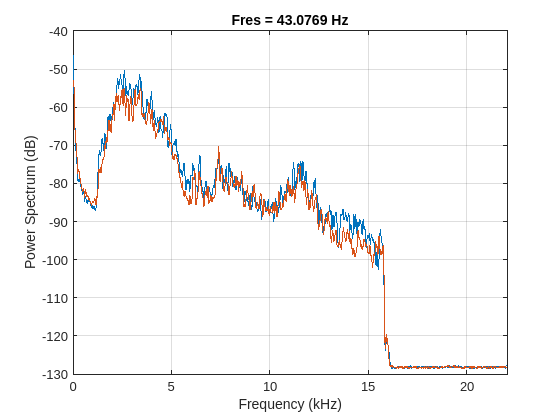

[birds, fsb] = audioread("./data/bird-call-in-spring.mp3");
pspectrum(birds, fsb)

## Task 2

There are two lines on the spectrum. Some audio files have two channels, for the left and right stereo.

If you just want a signal with one channel, you can choose one of the columns or average them together. To average each row, you can specify the dimension while you take the average.

`y` `=` `mean``(``x``,``2``)`

birds = mean(birds, 2);

## Task 3

Look in the workspace to compare the values of `fsup` and `fsb`. To use `birds` as the watermark, the sample rates should match.

You can resample `birds`, but you need choose both `p` and `q`. This is a convenient way to find the ratio:

`[``p``,``q``]` `=` `rat``(``fs_desired` `/` `fs_current``)`

[p, q] = rat(fsup / fsb)

p = 320

q = 441

## Task 4

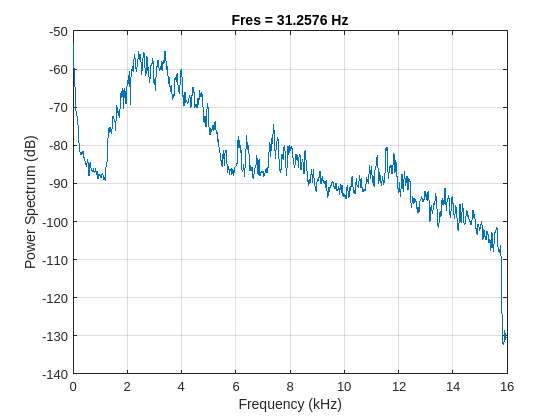

birdsdown = resample(birds, p, q);
pspectrum(birdsdown, fsup)